# Habituation Trials RAM

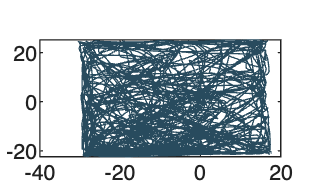

clear; close all; clc;

load(fullfile(get_behavior_root(),"HabituationData.mat"));
load(fullfile(get_behavior_root(),"DataRAM.mat"));

% Define variables
animals = length(occupancy);
positive = [6,8,9,10]; %maybe 11, check injection
negative = [2,3,4,5];


%Plot specifications
colors = {'#284B5E','#BC554C'};
noLine = {'none','none'};
linew = {3,3};

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
plot(occupancy{1,negative(1)}(:,1),occupancy{1,negative(1)}(:,2),'color','#284B5E');

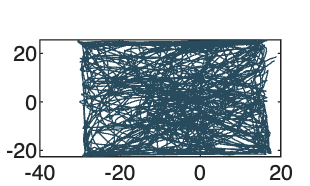

figure
plot(occupancy{1,negative(2)}(:,1),occupancy{1,negative(2)}(:,2),'color', '#284B5E');

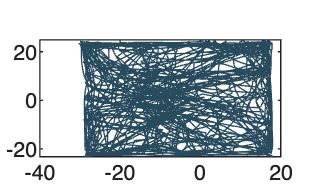

figure
plot(occupancy{1,negative(3)}(:,1),occupancy{1,negative(3)}(:,2),'color','#284B5E');

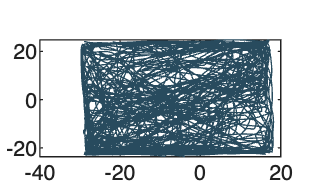

figure
plot(occupancy{1,negative(4)}(:,1),occupancy{1,negative(4)}(:,2),'color','#284B5E');

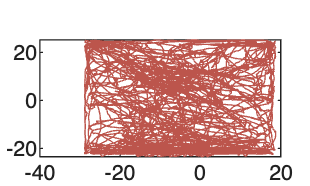

figure
plot(occupancy{1,positive(1)}(:,1),occupancy{1,positive(1)}(:,2),'color','#BC554C');

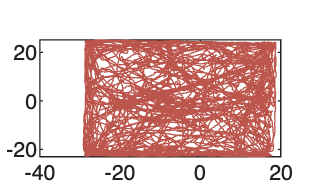

figure
plot(occupancy{1,positive(2)}(:,1),occupancy{1,positive(2)}(:,2),'color','#BC554C');

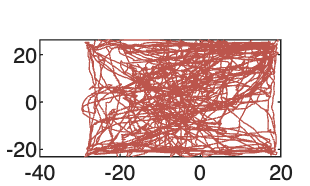

figure
plot(occupancy{1,positive(3)}(:,1),occupancy{1,positive(3)}(:,2),'color','#BC554C');

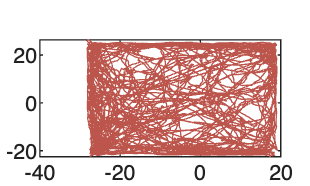

figure
plot(occupancy{1,positive(4)}(:,1),occupancy{1,positive(4)}(:,2),'color','#BC554C');



% Accumulated time in the middle of the maze 
ram_hab = entry_raw(2:5,1:animals);
occupancy_zone_of = nan(4,animals);

[l,w] = size(ram_hab);
for a = 1:w
    for t = 1:l
        if t == 1 % Do the processing for Open Field here
            path_of = traject(entry_raw{t,a});
            occupancy_zone_of(:,a) = histcounts(path_of)'; % counts in zones (vertical)
        end
        hab = ram_hab{t,a};
        [y,x] = find(hab');
        arm_time = zeros(length(hab),1);
        arm_time(x) = y;
        middle = find(~arm_time);
        time_center(t,a) = (length(middle)/25)/60; %sample time 25 frames per s => in minutes

        zone_dist(:,t) = arm_time;
    end
    center(1,a) = mean(time_center(:,a));
    zone_distribution{1,a} = zone_dist;
end
gen_center = [mean(center(negative)),mean(center(positive))];
[h,p_center] = ttest2(center(negative),center(positive))

h = 0

p_center = 0.1615

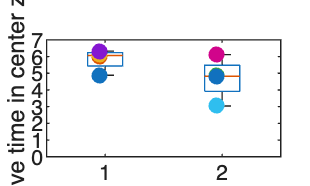


figure
boxplot([center(negative)',center(positive)']);
ylim([0 7])
yticks(0:1:7)
hold on
scatter(1,center(:,negative),'filled','jitter','on','jitterAmount',0.08);
scatter(2,center(:,positive),'filled','jitter','on','jitterAmount',0.08);
ylabel('Accumulative time in center zone (min)');

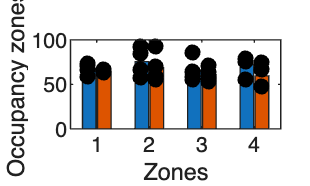


%%% Measure locomotion through zone alterations %%%
occupancy_gen = [mean(occupancy_zone_of(:,negative),2),mean(occupancy_zone_of(:,positive),2)];

figure
b = bar(occupancy_gen,'BarWidth',0.9);
hold on
scatter(0.85,occupancy_zone_of(1,negative),'filled','k','jitter','on','jitterAmount',0.04);
scatter(1.15,occupancy_zone_of(1,positive),'filled','k','jitter','on','jitterAmount',0.04);
scatter(1.85,occupancy_zone_of(2,negative),'filled','k','jitter','on','jitterAmount',0.04);
scatter(2.15,occupancy_zone_of(2,positive),'filled','k','jitter','on','jitterAmount',0.04)
scatter(2.85,occupancy_zone_of(3,negative),'filled','k','jitter','on','jitterAmount',0.04);
scatter(3.15,occupancy_zone_of(3,positive),'filled','k','jitter','on','jitterAmount',0.04)
scatter(3.85,occupancy_zone_of(4,negative),'filled','k','jitter','on','jitterAmount',0.04);
scatter(4.15,occupancy_zone_of(4,positive),'filled','k','jitter','on','jitterAmount',0.04)
ylabel('Occupancy zones');
xlabel('Zones');

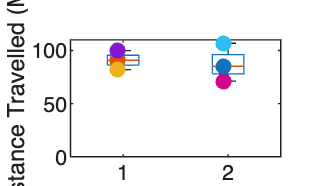



%distance traveled
moved_of = sum(open_field_move,'omitnan')/100;
moved = [mean(moved_of(negative)),mean(moved_of(positive))];
int = max([numel(positive),numel(negative)]);
box_initialize = nan(int,2);
idx = find(moved_of(negative)');
box_initialize(idx,1) = moved_of(negative)';
box_initialize(:,2) = moved_of(positive);

figure
b = boxplot(box_initialize);
ylim([0 110])
hold on
scatter(1,moved_of(1,negative),'filled','jitter','on','jitterAmount',0.08);
scatter(2,moved_of(1,positive),'filled','jitter','on','jitterAmount',0.08);
ylabel('Distance Travelled (M)');

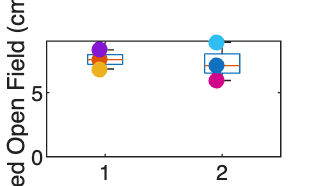


[h,p] = ttest2(box_initialize(:,1),box_initialize(:,2));

speed_of_mean = [mean(speed_open_field(:,negative),'omitnan'); mean(speed_open_field(:,positive),'omitnan')];

figure
boxplot(speed_of_mean')
hold on
scatter(1,speed_of_mean(1,:),'filled','jitter','on','jitterAmount',0.08);
scatter(2,speed_of_mean(2,:),'filled','jitter','on','jitterAmount',0.08);
ylabel('Speed Open Field (cm/s)');
ylim([0 9])


%p = 0.626
[h,p] = ttest(speed_of_mean(1,:),speed_of_mean(2,:));

## Spontaneous Alterating Behavior

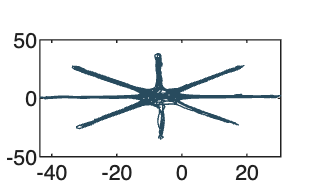

% use rawdata for entries in habituation trails (first 4 of each animal)
for a = 1:animals
    for t = 2:5
        ram_occupancy{t-1,a} = table2array(Data.animal(a).trial(t).name(:,3:4)); %3D Matrix
        
    end
end

figure
xy = ram_occupancy{:,negative(1)};
plot(xy(:,1),xy(:,2),'color','#284B5E')

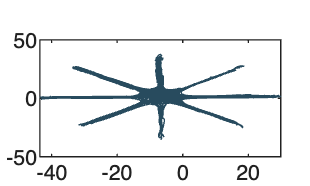


xy = ram_occupancy{:,negative(2)};
figure
plot(xy(:,1),xy(:,2),'color','#284B5E')

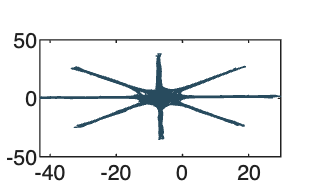


xy = ram_occupancy{:,negative(3)};
figure
plot(xy(:,1),xy(:,2),'color','#284B5E')

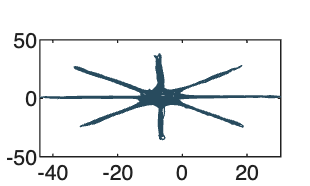


xy = ram_occupancy{:,negative(4)};
figure
plot(xy(:,1),xy(:,2), 'color','#284B5E')

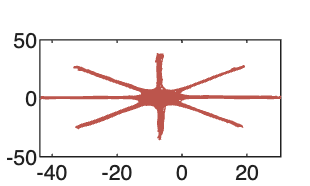



xy = ram_occupancy{:,positive(1)};
figure
plot(xy(:,1),xy(:,2),'color','#BC554C')



xy = ram_occupancy{:,positive(1)};
figure
plot(xy(:,1),xy(:,2),'color','#BC554C')

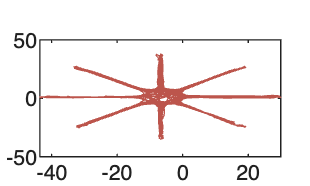



xy = ram_occupancy{:,positive(2)};
figure
plot(xy(:,1),xy(:,2),'color','#BC554C')

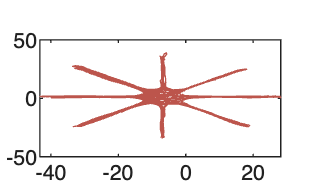




xy = ram_occupancy{:,positive(3)};
figure
plot(xy(:,1),xy(:,2),'color','#BC554C')

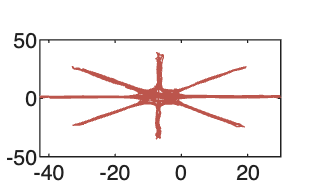



xy = ram_occupancy{:,positive(4)};
figure
plot(xy(:,1),xy(:,2),'color','#BC554C')

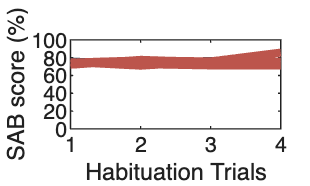




% Using a sliding window of 8 (but unlikely that they explore 8 arms consecutively, try 4)
sab_score = SAB(entry_raw(2:5,1:animals),animals,4).*100;

figure 
plot(sab_score(:,negative),'color','#284B5E','LineWidth',3)
ylim([0 100]);
yticks(0:20:100);
ylabel('SAB score (%)');
xlabel('Habituation Trials');
xlim([1 4]);
xticks(1:1:5);
hold on
plot(sab_score(:,positive),'color','#BC554C','LineWidth',3)